clear;
clc;

set( groot, 'defaultLineLineWidth', 1.2 ) ; % plot line 두께 지정
set( groot, 'defaultAxesXGrid', 'on' ) ; % x축 방향으로 grid 생성
set( groot, 'defaultAxesYGrid', 'on' ) ; % y축 방향으로 grid 생성
set( groot, 'defaultAxesTitleFontSizeMultiplier', 1.5);  % Title 크기 설정
set( groot, 'defaultAxesFontSize', 12 ); % 축에 있는 글씨 크기 지정
set( groot, 'defaultAxesFontName', 'Times New Roman'); % 축에 있는 글씨 폰트 지정
set( groot, 'defaultFigureColor', 'w'); % figure 색상

% Load Estimate target pose data
dateStr = '20250630';      % log date
runIdx  = '1';             % log nums

scriptFullPath = matlab.desktop.editor.getActiveFilename;
currentDir = fileparts(scriptFullPath);

while true
    [parentDir, folderName] = fileparts(currentDir);
    if strcmp(folderName, 'mppi_solver')
        projectRoot = currentDir;
        break;
    end
    if isempty(parentDir)
        error('Directory mppi_solver not found');
    end
    currentDir = parentDir;
end

absPath = fullfile(projectRoot, 'runs', ...
                   dateStr, runIdx, 'kalman_target_state');

true_target_pose = h5read(fullfile(absPath, 'target_pose.mat'), '/true_pose' );
true_target_vel = h5read(fullfile(absPath, 'target_pose.mat'), '/vel' );
true_target_mean_vel = h5read(fullfile(absPath, 'target_pose.mat'), '/mean_vel' );

clearvars dateStr runIdx scriptFullPath currentDir parentDir folderName projectRoot absPath

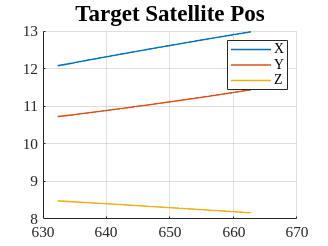

sim_time = true_target_pose(1,:);
true_target_pose_x = true_target_pose(2,:);
true_target_pose_y = true_target_pose(3,:);
true_target_pose_z = true_target_pose(4,:);

figure;
hold on
plot(sim_time, true_target_pose_x);
plot(sim_time, true_target_pose_y);
plot(sim_time, true_target_pose_z);
hold off
title("Target Satellite Pos")
legend("X", "Y", "Z")

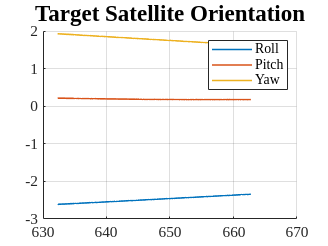


true_target_pose_roll  = true_target_pose(5,:);
true_target_pose_pitch = true_target_pose(6,:);
true_target_pose_yaw   = true_target_pose(7,:);

figure;
hold on
plot(sim_time, true_target_pose_roll);
plot(sim_time, true_target_pose_pitch);
plot(sim_time, true_target_pose_yaw);
hold off
title("Target Satellite Orientation")
legend("Roll", "Pitch", "Yaw")

if size(true_target_pose, 2) ~= size(true_target_vel, 2)
    true_target_vel = true_target_vel(:,1:end-1);
end

if (2 *size(true_target_pose, 2)) == size(true_target_vel, 2)
    true_target_vel = true_target_vel(:,2:2:end);
end

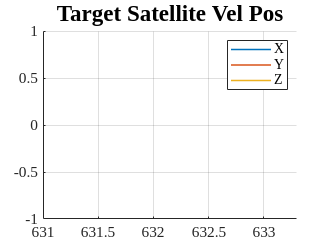

sim_time = true_target_vel(1,:);
true_target_vel_x = true_target_vel(2,:);
true_target_vel_y = true_target_vel(3,:);
true_target_vel_z = true_target_vel(4,:);

figure;
hold on
plot(sim_time, true_target_vel_x);
plot(sim_time, true_target_vel_y);
plot(sim_time, true_target_vel_z);
hold off
title("Target Satellite Vel Pos")
legend("X", "Y", "Z")

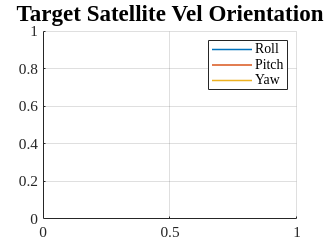


true_target_vel_roll = true_target_vel(5,:);
true_target_vel_pitch = true_target_vel(6,:);
true_target_vel_yaw = true_target_vel(7,:);

figure;
hold on
plot(sim_time, true_target_vel_roll);
plot(sim_time, true_target_vel_pitch);
plot(sim_time, true_target_vel_yaw);
hold off
title("Target Satellite Vel Orientation")
legend("Roll", "Pitch", "Yaw")

if size(true_target_pose, 2) ~= size(true_target_mean_vel, 2)
    true_target_mean_vel = true_target_mean_vel(:,1:end-1);
end

if (2 *size(true_target_pose, 2)) == size(true_target_mean_vel, 2)
    true_target_mean_vel = true_target_mean_vel(:,1:2:end)
end

sim_time = true_target_mean_vel(1,:);
true_target_vel_x = true_target_mean_vel(2,:);
true_target_vel_y = true_target_mean_vel(3,:);
true_target_vel_z = true_target_mean_vel(4,:);

figure;
hold on
plot(sim_time, true_target_vel_x);
plot(sim_time, true_target_vel_y);
plot(sim_time, true_target_vel_z);
hold off
title("Target Satellite Vel Pos")
legend("X", "Y", "Z")


true_target_vel_roll = true_target_mean_vel(5,:);
true_target_vel_pitch = true_target_mean_vel(6,:);
true_target_vel_yaw = true_target_mean_vel(7,:);

figure;
hold on
plot(sim_time, true_target_vel_roll);
plot(sim_time, true_target_vel_pitch);
plot(sim_time, true_target_vel_yaw);
hold off
title("Target Satellite Vel Orientation")
legend("Roll", "Pitch", "Yaw")